clc;
clear;
close all;

%% Carga del modelo
load('modelo_lin.mat')

modelo = linmodel

modelo =
 
  A = 
                 phi       theta         psi           p           q           r           u           v           w          Xe          Ye
   phi    -1.455e-24   3.676e-24           0           1  -9.266e-05     0.05385           0           0           0           0           0
   theta  -3.665e-24           0           0           0           1    0.001721           0           0           0           0           0
   psi    -2.706e-23   1.976e-25           0           0   -0.001723       1.001           0           0           0           0           0
   p               0           0           0      -16.14     -0.1393       3.377     0.06442      -2.831    0.003345   2.699e-09  -2.458e-09
   q               0           0           0   3.493e-24      -15.85       1.243       1.042  -6.238e-22      -7.427   7.059e-21  -6.429e-21
   r               0           0           0      0.5154     -0.7116      -2.783     0.00587       1.706   0.0003079   2.459e-10   -2.24


Alin = modelo.A;
Blin = modelo.B;
Clin = modelo.C;
Dlin = modelo.D;

%% Eliminacion de datos irrelevantes
Alin(abs(Alin)<1e-10)=0;
Blin(abs(Blin)<1e-10)=0;
Clin(abs(Clin)<1e-10)=0;
Dlin(abs(Dlin)<1e-10)=0;

%% Seleccion de estados
modelo

modelo =
 
  A = 
                 phi       theta         psi           p           q           r           u           v           w          Xe          Ye
   phi    -1.455e-24   3.676e-24           0           1  -9.266e-05     0.05385           0           0           0           0           0
   theta  -3.665e-24           0           0           0           1    0.001721           0           0           0           0           0
   psi    -2.706e-23   1.976e-25           0           0   -0.001723       1.001           0           0           0           0           0
   p               0           0           0      -16.14     -0.1393       3.377     0.06442      -2.831    0.003345   2.699e-09  -2.458e-09
   q               0           0           0   3.493e-24      -15.85       1.243       1.042  -6.238e-22      -7.427   7.059e-21  -6.429e-21
   r               0           0           0      0.5154     -0.7116      -2.783     0.00587       1.706   0.0003079   2.459e-10   -2.24

Blin=Blin(:,[2,3,8])

Blin =          0         0         0
         0         0         0
         0         0         0
         0   -5.0216 -156.9094
 -134.0661   -0.0046   -1.3520
         0  -82.2714   11.5366
    0.4681   -0.8409   -0.3867
         0    5.3170         0
   -2.7109   -0.0453  -13.2450
         0         0         0


Clin=Clin([5,6,7],:)

Clin =     1.0000         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.0000         0         0         0         0         0         0         0         0         0         0         0
         0         0    1.0000         0         0         0         0         0         0         0         0         0         0


Dlin=Dlin([5,6,7],[2,3,8])

Dlin =      0     0     0
     0     0     0
     0     0     0


G=ss(Alin,Blin,Clin,Dlin)

G =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8          x9         x10         x11         x12
   x1            0           0           0           1  -9.266e-05     0.05385           0           0           0           0           0           0
   x2            0           0           0           0           1    0.001721           0           0           0           0           0           0
   x3            0           0           0           0   -0.001723       1.001           0           0           0           0           0           0
   x4            0           0           0      -16.14     -0.1393       3.377     0.06442      -2.831    0.003345   2.699e-09  -2.458e-09  -0.0003059
   x5            0           0           0           0      -15.85       1.243       1.042           0      -7.427           0           0           0
   x6            0           0           0      0.5154     -0.7116      -2.783   


%% Filtros
s=tf('s');

wB1=8*2*pi;
A1=0.0003;
M1=0.3;

wB3=6*2*pi;
A3=0.1;
M3=1;

% W1=(0.5*s+0.015)/(s+0.00015);
W1=[(s/M1+wB1)/(s+wB1*A1) 0 0;
    0 (s/M1+wB1)/(s+wB1*A1) 0;
    0 0 (s/M1+wB1)/(s+wB1*A1)];
W2=[tf(1,1) 0 0;
    0 tf(1,1) 0;
    0 0 tf(1,1)];
W3=[(1+s/M3)/(1+(s/wB3)) 0 0;
    0 (1+s/M3)/(1+(s/wB3)) 0;
    0 0 (1+s/M3)/(1+(s/wB3))];

%% Grafica de filtros
% hold on
% bodemag(1/W1,'r');
% bodemag(1/W2,'g');
% bodemag(1/W3,'b');
% hold off

%% Calculo del controlador
[K,CL,gamma]=mixsyn(G,W1,W2,W3)

K =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8          x9         x10         x11         x12
   x1     -0.01508   4.158e-32   2.871e-31  -1.993e-30   -2.46e-32  -5.278e-32  -1.776e-15  -1.987e-17  -8.086e-17  -2.862e-32   -3.57e-34  -6.101e-33
   x2     -2.9e-30    -0.01508  -1.074e-28   2.619e-31  -2.978e-30   2.844e-29   7.987e-16  -2.665e-15   3.187e-14   3.615e-32  -5.395e-32   9.547e-31
   x3    -1.24e-31   2.433e-30    -0.01508  -8.183e-32  -6.815e-31   4.757e-30   2.179e-17   -6.17e-16   5.329e-15   4.576e-33  -1.195e-32   1.587e-31
   x4      1.6e-23   1.306e-25   2.595e-21       -37.7   3.112e-24  -6.874e-22          32   -3.76e-11  -7.699e-07  -4.873e-25   2.026e-25  -2.329e-23
   x5    3.112e-25   4.933e-27   7.808e-23    4.18e-25       -37.7  -2.068e-23  -3.764e-11          32  -2.316e-08  -1.382e-26   6.094e-27  -7.006e-25
   x6    9.325e-21   1.109e-22   2.821e-18   1.577e-20   3.407e-21       -37.7  -

gamma = 2.7113e+04




%% Conexion de planta
OL=series(K,G)

OL =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8          x9         x10         x11         x12
   x1            0           0           0           1  -9.266e-05     0.05385           0           0           0           0           0           0
   x2            0           0           0           0           1    0.001721           0           0           0           0           0           0
   x3            0           0           0           0   -0.001723       1.001           0           0           0           0           0           0
   x4            0           0           0      -16.14     -0.1393       3.377     0.06442      -2.831    0.003345   2.699e-09  -2.458e-09  -0.0003059
   x5            0           0           0           0      -15.85       1.243       1.042           0      -7.427           0           0           0
   x6            0           0           0      0.5154     -0.7116      -2.783  

% 
I = eye(3)

I =      1     0     0
     0     1     0
     0     0     1


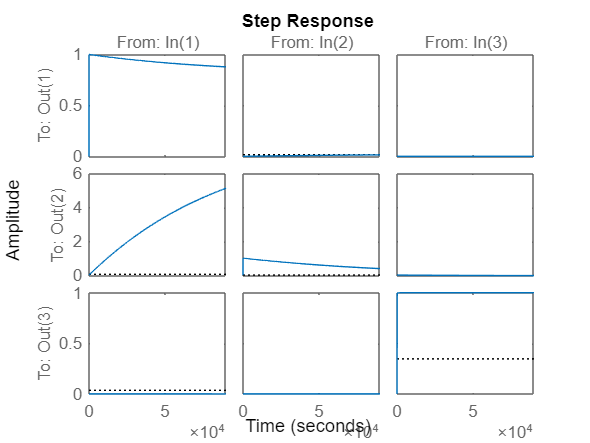

% 
GCL=feedback(OL,I);

figure (1)
step(GCL)

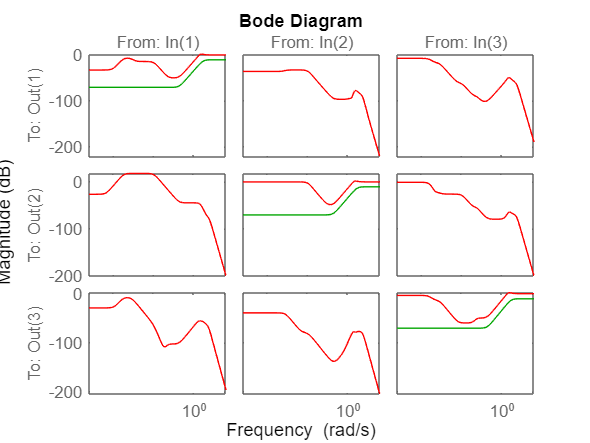

% 
% % step(CL), xlim([0 10])
%% Comprobación W1
S = feedback(I,OL);
figure (2)
bodemag(S,'r');
hold on
bodemag(1/W1,'g');
hold off

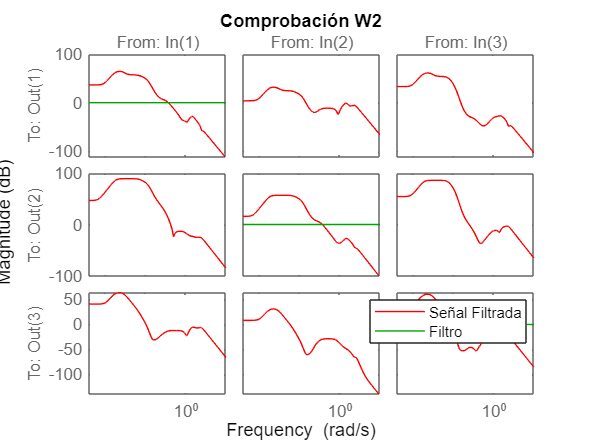


%Comprobación W2
S = feedback(I,OL);
figure(3)
bodemag(S*K,'r');
hold on
bodemag(1/W2,'g'), title("Comprobación W2");
legend("Señal Filtrada", "Filtro");
hold off

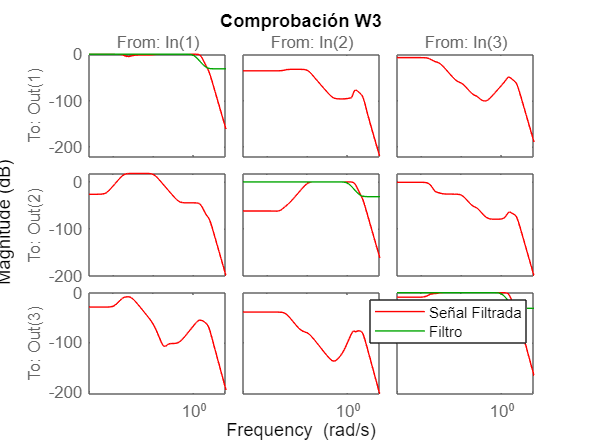


%% Comprobacion W3

T = feedback(OL,I);
figure (4)
bodemag(T,'r');
hold on
bodemag(1/W3,'g'), title("Comprobación W3");
legend("Señal Filtrada", "Filtro");
hold off